clc; clear; close all;

# 1D-FC With Lagrangian Polynomial Interpolation

Performed on y = x with space step k from x=0 to x=1

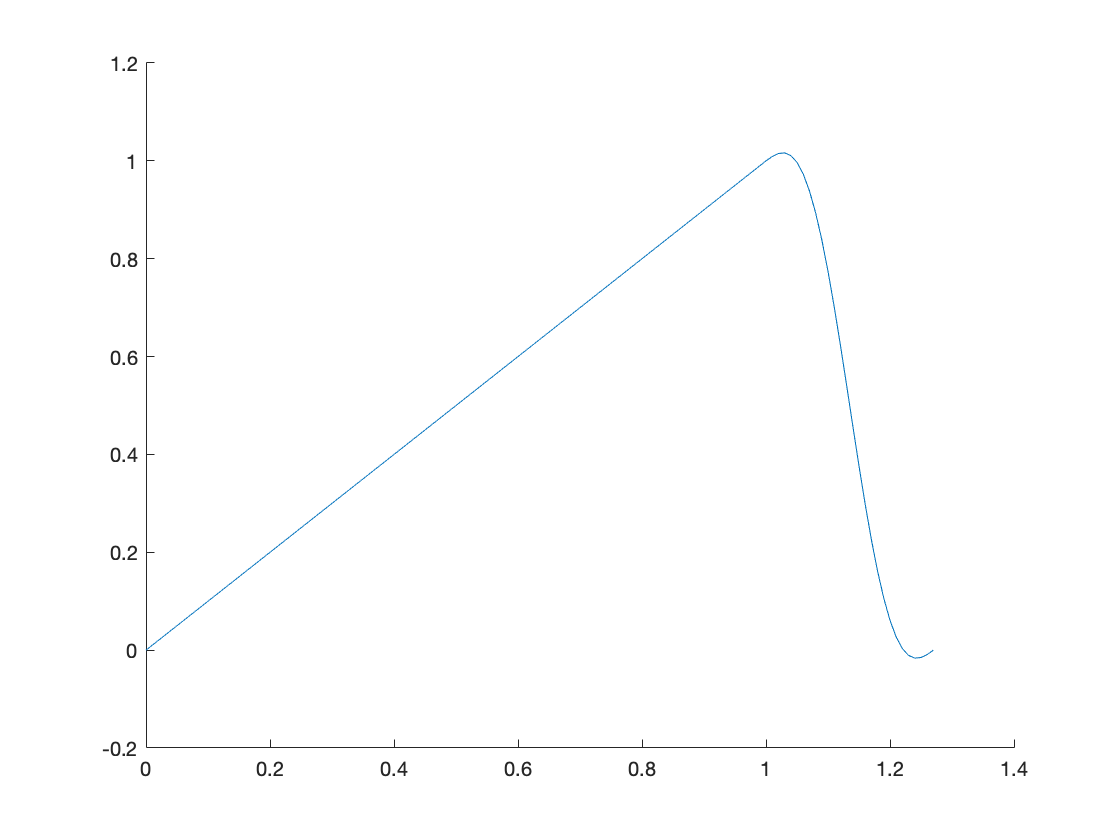

k = 0.01;

% x mesh
D = transpose(0:k:1);
N = length(D);

% dimension and continuation points
d = 4;
C = 27;

phi = @(x) x;

% left and right side of domain
D_l = D(1:d);
D_r = D(end-d+1:end);

% shifted left side for computation
D_l_C = D_l + (N+C-1)*k;

% value of function on left and right side
phi_l = phi(D_l);
phi_r = phi(D_r);

% grid values of interpolation
D_interpolant = [D_r; D_l_C];
phi_interpolant = [phi_r; phi_l];

w = barycentric_weights(D_interpolant);

% continuation vector
phi_C = zeros(1, C-1);
D_C = transpose(D_r(end)+k:k:D_r(end)+(C-1)*k);

barycentric_func = barycentric_compute_func(w, phi_interpolant, D_interpolant);

phi_C = barycentric_func(D_C);

phi_FC = [phi(D); phi_C; phi(0)];
D_FC = 0:k:(N+C-1)*k;

figure;
hold on;
plot(D_FC, phi_FC)

# Fast Fourier Transform for y=x

from x = 0 to x = 1

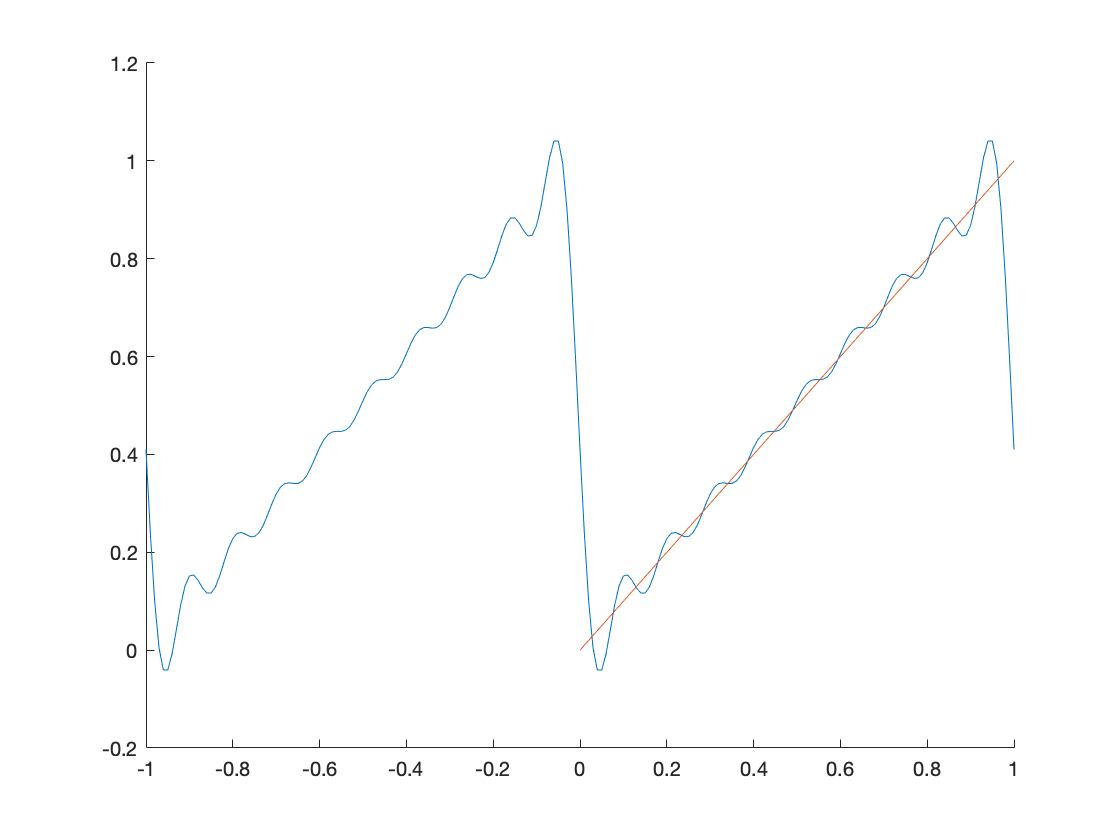

k = 0.01;

% x mesh
D = transpose(0:k:1);
N = length(D);

phi = @(x) x;

% original
phi_D = phi(D);
C_n = FFT_coeff(phi_D, 10);
FS_func = FFT_compute_func(C_n);

% continuation
C_FC = FFT_coeff(phi_FC, 10);
FS_FC_func = FFT_compute_func(C_FC);

figure;
hold on;

%plot((0:k:1).*D_FC(end), FS_phi)
plot(transpose(-1:k:1), FS_func(transpose(-1:k:1)))
fplot(phi, [0, 1])
hold off;

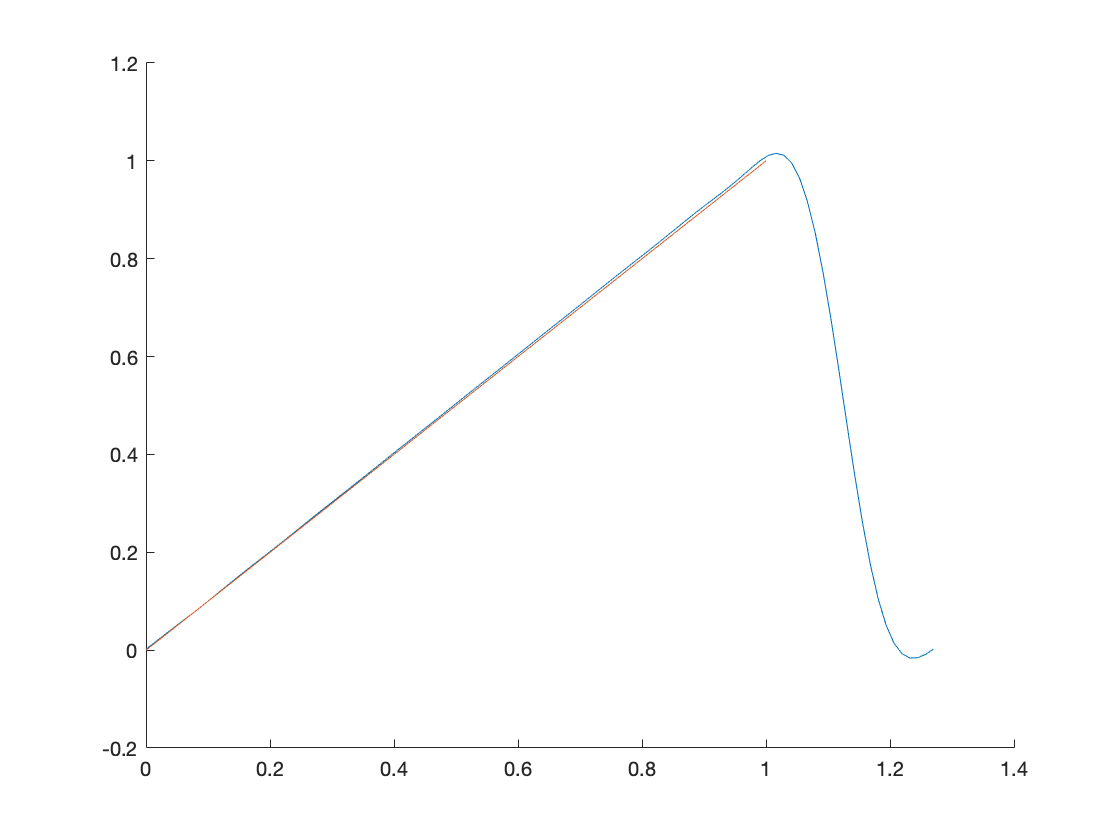


figure;
hold on;
plot((0:k:1).*D_FC(end), FS_FC_func(transpose(0:k:1)))
fplot(phi, [0, 1])
hold off

# Order Analysis of Lagrangian Polynomial

For phi = x

digits(30)

k_lst = [0.01, 0.005, 0.0025, 0.00125, 0.000625];
k_err = 0.0000625;
d_lst = 2:5;
interpolant_err = zeros(length(d_lst), length(k_lst));
phi = @(x) cos(x);

for i = 1:length(d_lst)
    d = d_lst(i);
    for j = 1:length(k_lst)
        k = k_lst(j);
    
        % x mesh
        D = transpose(0:k:1);
        N = length(D);
        
        % dimension and continuation points
    
        C = 27;
        
        % left and right side of domain
        D_l = D(1:d);
        D_r = D(end-d+1:end);
        
        % shifted left side for computation
        D_l_C = D_l + (N+C-1)*k;
        
        % value of function on left and right side
        phi_l = phi(D_l);
        phi_r = phi(D_r);
        
        % grid values of interpolation
        D_interpolant = [D_r; D_l_C];
        phi_interpolant = [phi_r; phi_l];
        
%         D_interpolant = D_r;
%         phi_interpolant = phi_r;
        
        [W_j, W_k] = meshgrid(D_interpolant);
        W_j(logical(eye(2*d))) = 1;
        W_k(logical(eye(2*d))) = 0;

%         [W_j, W_k] = meshgrid(D_interpolant);
%         W_j(logical(eye(d))) = 1;
%         W_k(logical(eye(d))) = 0;
        
        w = barycentric_weights(D_interpolant);
        barycentric_func = barycentric_compute_func(w, phi_interpolant, D_interpolant);
        
        D_l_err_mesh = transpose(D_l(1):k_err:D_l(end));
        D_r_err_mesh = transpose(D_r(1):k_err:D_r(end));
        D_l_C_err_mesh = transpose(D_l_C(1):k_err:D_l_C(end));
        
        D_err_mesh = [D_r_err_mesh; D_l_C_err_mesh];
        phi_err_mesh = [phi(D_r_err_mesh); phi(D_l_err_mesh)];

%         D_err_mesh = [D_r_err_mesh;];
%         phi_err_mesh = [phi(D_r_err_mesh)];

        
        interpolant_err_mesh = barycentric_func(D_err_mesh);
        interpolant_err_mesh(1:round(k/k_err):d*round(k/k_err)) = phi(D_r);
        interpolant_err_mesh((d-1)*round(k/k_err)+2:round(k/k_err):length(interpolant_err_mesh)) = phi(D_l);
        
        interpolant_err(i, j) = norm(phi_err_mesh - interpolant_err_mesh);
    end
    
end
interpolant_err

interpolant_err =      7.166812946551236e-03     4.568398392303802e-03     3.053544313051166e-03     2.096537178226737e-03     1.460230990069509e-03
     1.644284950306646e-03     1.050844149245504e-03     7.028412395674663e-04     4.826415241481652e-04     3.361666386497015e-04
     4.833558769057011e-04     3.091730632485644e-04     2.068300728390054e-04     1.420376962641003e-04     9.892973098943337e-05
     1.813574883139362e-04     1.160515060440500e-04     7.764399377673418e-05     5.332218361216849e-05     3.713776137375502e-05


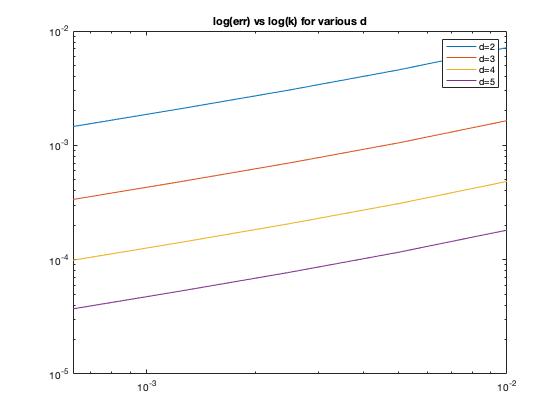


figure;
loglog(k_lst, interpolant_err')
%plot(log(k_lst), log(interpolant_err)');
title("log(err) vs log(k) for various d")
legend('d=2', 'd=3', 'd=4', 'd=5')


% figure;
% plot(log2(d_lst), log2(interpolant_err));
% title("log(err) vs log(d) for various k")
% legend('k=0.01', 'k=0.005', 'k=0.0025', 'k=0.00125', 'k=0.000625')